% Problem 0
load('Homework5.mat')

% Problem 1

% Prepare data
passed = score1(pass1==1);
failed = score1(pass1==0);

passed_mean = mean(passed);
failed_mean = mean(passed);

% percentile
prct_passed = prctile(passed,[2.5 50 97.5]);
prct_failed = prctile(failed,[2.5 50 97.5]);




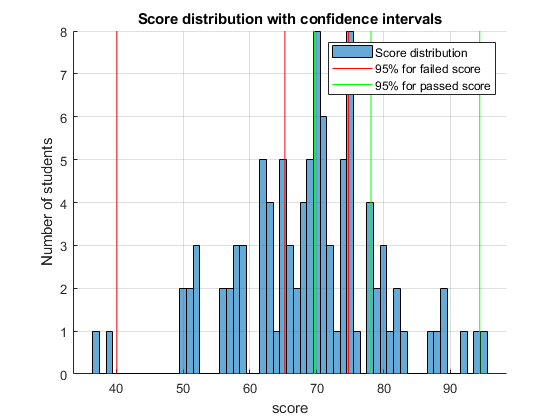


% Visualize the distribution
figure; hold on;



h1 = histogram(score1, 50,'BinMethod','integers');
xlabel('score');
ylabel('Number of students');
grid;


f_h = plot([prct_failed; prct_failed], repmat(ylim',1,size(prct_failed,2)), '-r');
p_h = plot([prct_passed; prct_passed], repmat(ylim',1,size(prct_passed,2)), '-g');


legend([h1 f_h(2) p_h(2)], {'Score distribution' '95% for failed score' '95% for passed score'})
title('Score distribution with confidence intervals');

% Visualize
% Passed score
figure; hold on;

h1 = scatter(passed, ones(length(passed),1),'d','filled');
h2 = scatter(failed, zeros(length(failed),1),'d','filled');
legend([h1 h2], {'Passed' 'Failed'});
title('Plot of passed/failed score distribution');

ax = axis;
x = linspace(ax(1),ax(2),100);

% Model definition
% That model is absolutely wrong, but we will still have to test it

a = 1;
b = -72;

modelfunc = @(score, params) 1./(1 + exp( -1*(params(1)*score + params(2))));


y = modelfunc(x,[a b]);


model_1 = plot(x,y,'-g');
xlabel('score');
ylabel('passing');
title('Exam passing model visualization');

% Evaluate the model on the score sample
f = modelfunc(score1,[a b]);

% Likehood of the data points labeled 0
lik0 = prod(1 - f(pass1==0));

% Likehood of the data points labeled 1
lik1 = prod(f(pass1==1));

% Total likelihood
likelihood1 = lik0 * lik1;


% Calculte percent correct achieved by the model
modelfit = (f>=0.5);
acc = sum(modelfit == pass1) / length(modelfit) * 100;

fprintf('Likelihood the model with a=%g,b=%g is %.2f%%',a,b,likelihood1);

Likelihood the model with a=1,b=-72 is 0.00%

fprintf('Accuracy for the model with a=%g,b=%g is %.2f%%',a,b,acc);

Accuracy for the model with a=1,b=-72 is 91.00%

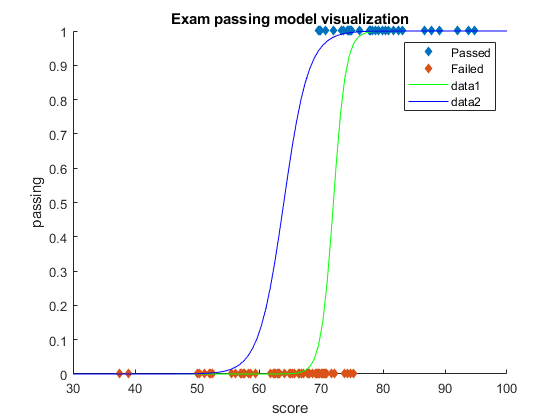




% Change the a and the b parameters
a = 0.5;
b = -32;

y = modelfunc(x,[a b]);

model_2 =plot(x,y,'-b');
xlabel('score');
ylabel('passing');
title('Exam passing model visualization');


% Evaluate the model on the score sample
f = modelfunc(score1,[a b]);

% Likehood of the data points labeled 0
lik0 = prod(1 - f(pass1==0));

% Likehood of the data points labeled 1
lik1 = prod(f(pass1==1));

% Total likelihood
likelihood2 = lik0 * lik1;


% Calculte percent correct achieved by the model
modelfit = (f>=0.5);
acc = sum(modelfit == pass1) / length(modelfit) * 100;

fprintf('Likelihood the model with a=%g,b=%g is %.2f%% ',a,b,likelihood2);

Likelihood the model with a=0.5,b=-32 is 0.00% 

fprintf('Accuracy for the model with a=%g,b=%g is %.2f%%',a,b,acc);

Accuracy for the model with a=0.5,b=-32 is 64.00%

% which likelihood is bigger? 
[mx,ix] = max([likelihood1, likelihood2]);
% report 
fprintf('case %d has the higher likelihood.\n',ix); 

case 1 has the higher likelihood.


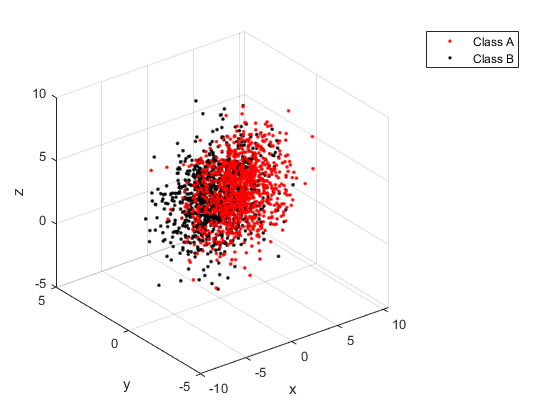

% Problem 2
figure; hold on;
grid;
view(3);


X_a = classA(:,1);
Y_a = classA(:,2);
Z_a = classA(:,3);

X_b = classB(:,1);
Y_b = classB(:,2);
Z_b = classB(:,3);


a = scatter3(X_a,Y_a,Z_a,'r.');
b = scatter3(X_b,Y_b,Z_b,'k.');

ax = axis;
% Problem 2



legend([a,b], {'Class A' 'Class B'})
xlabel('x');
ylabel('y');
zlabel('z');

nA = size(classA,1);
nB = size(classB,1);

X = [classA; classB;];

y = [zeros(nA,1); ...
     ones(nB,1)];
 
% initialize prediction vector
pred = zeros(nA+nB,1);

% perform leave-one-out cross validation
for p=1:length(y)
    
    % training and testing indices
    trainix = setdiff(1:length(y),p);
    testix = p;
    
    % use classify.m to perform LDA. we train on the data points in trainix
    % and predict the class assignment for the data points in testix. we
    % save the predicted class assignment in the appropriate spot in pred.
    
    pred(testix) = classify(X(testix,:), X(trainix, :), y(trainix), 'linear');
    
end

% calculate percent correct and report to window

pctcorrect = sum(pred == y) / length(y) * 100;
fprintf('Class assignment successfully predicted %.1f%% of the time. \n', pctcorrect);

Class assignment successfully predicted 77.1% of the time. 
